dataPath = 'E:\PhoHaleScratchFolder';
dateStrings = {'20200117','20200120','20200124'}; % Strings representing each date.
[rawOutpaths, registeredOutpaths] = fnBuildPaths(dateStrings);

numberOfDays = length(registeredOutpaths);

% Allocate output structures:


I = imread(imds.Files{1},1:16);
info = imfinfo(imds.Files{1}) % Returns a 2000x1 info struct for each frame in this file


% Load first and second days:
prevIndex = 1;
nextIndex = 2;

% Get the tif paths for each
registeredTifFolder_prev = registeredOutpaths{prevIndex}.tifFolder;
registeredTifFolder_next = registeredOutpaths{nextIndex}.tifFolder;

% Set the datasources
imds.registered_prev.ReadFcn = @fnCustomTifStackReader;
imds.registered_next.ReadFcn = @fnCustomTifStackReader;

% Load the datasources
imds.registered_prev = imageDatastore(registeredTifFolder_prev,'IncludeSubfolders',false,'FileExtensions','.tif','LabelSource','foldernames');
imds.registered_next = imageDatastore(registeredTifFolder_next,'IncludeSubfolders',false,'FileExtensions','.tif','LabelSource','foldernames');

% Extract information from the loaded datastores
registered_imageInfo_prev.count = size(imds.registered_prev.Files, 1);
registered_imageInfo_next.count = size(imds.registered_next.Files, 1);

% Get prev/next index:
registered_imageInfo_prev.last_index = registered_imageInfo_prev.count;
registered_imageInfo_next.first_index = 1;



% Load the current data:
registered_imageInfo_prev.fileName = imds.registered_prev.Files{registered_imageInfo_prev.last_index} % Get the last index of the previous one

registered_imageInfo_prev = struct with fields:
         count: 39
    last_index: 39
      fileName: 'Z:\ICPassiveStim\anm265\20200117_PassiveStim_Registered\FoV1Lateral\suite2p\plane0\reg_tif\file038_chan0.tif'


registered_imageInfo_prev.currLoadedData = bfOpen3DVolume(registered_imageInfo_prev.fileName);

Reading series #1
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ......................................................

registered_imageInfo_prev.currLoadedImgStack = registered_imageInfo_prev.currLoadedData{1,1}{1,1}; % Produces the desired 512x512x2000 (2000 frames per .tif) output
registered_imageInfo_prev.imgStackSize.numberOfFrames = size(registered_imageInfo_prev.currLoadedImgStack,3);

registered_imageInfo_next.fileName = imds.registered_next.Files{registered_imageInfo_next.first_index} % Get the first index of the next one

registered_imageInfo_next = struct with fields:
          count: 39
    first_index: 1
       fileName: 'Z:\ICPassiveStim\anm265\20200120_PassiveStim_Registered\FoV1Lateral\suite2p\plane0\reg_tif\file000_chan0.tif'


registered_imageInfo_next.currLoadedData = bfOpen3DVolume(registered_imageInfo_next.fileName);

Reading series #1
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ......................................................

registered_imageInfo_next.currLoadedImgStack = registered_imageInfo_next.currLoadedData{1,1}{1,1}; % Produces the desired 512x512x2000 (2000 frames per .tif) output
registered_imageInfo_next.imgStackSize.numberOfFrames = size(registered_imageInfo_next.currLoadedImgStack,3);

## Individual Frame Level

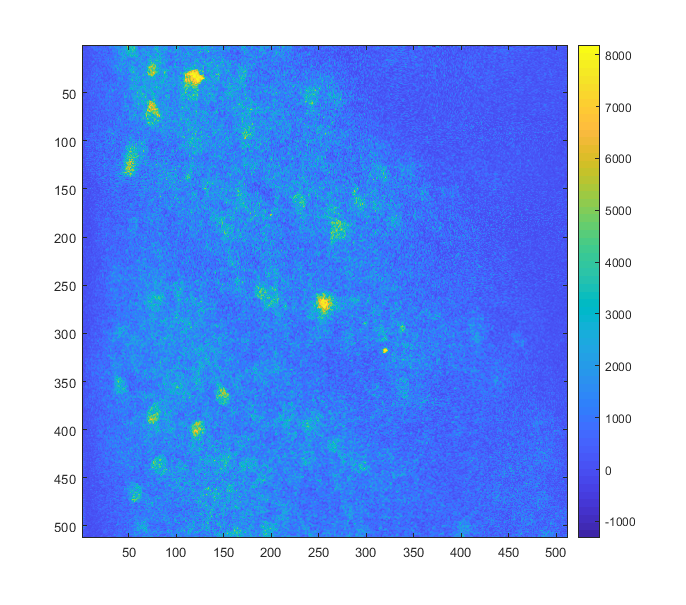

ans =   Image with properties:

           CData: [512×512 int16]
    CDataMapping: 'scaled'

  Show all properties


% Load the last frame of the prev day and the first frame of the next day
registered_imageInfo_prev.currRegisteredImage = registered_imageInfo_prev.currLoadedImgStack(:,:,registered_imageInfo_prev.imgStackSize.numberOfFrames); % Get the last from the first prev stack
registered_imageInfo_next.currRegisteredImage = registered_imageInfo_next.currLoadedImgStack(:,:,1); % Get first frame from the next stack

% imshow(registered_imageInfo_prev.currRegisteredImage)
% imshow(registered_imageInfo_next.currRegisteredImage)

fnPhoMatrixPlot(registered_imageInfo_prev.currRegisteredImage)

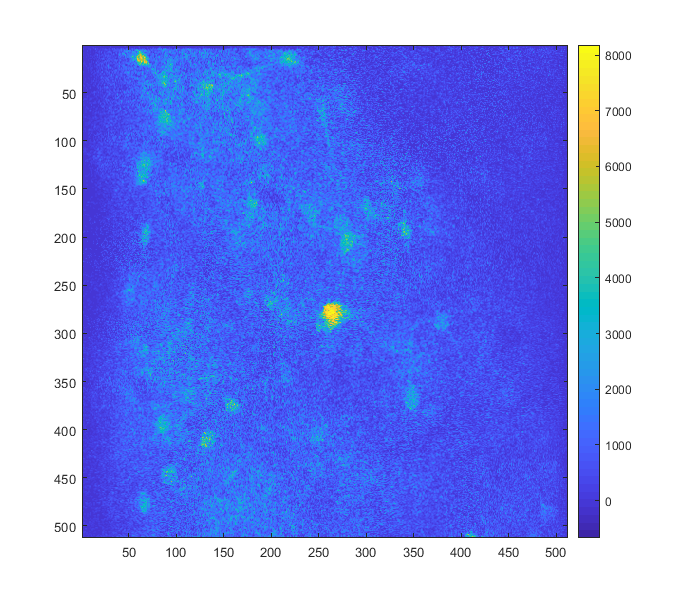

ans =   Image with properties:

           CData: [512×512 int16]
    CDataMapping: 'scaled'

  Show all properties


fnPhoMatrixPlot(registered_imageInfo_next.currRegisteredImage)

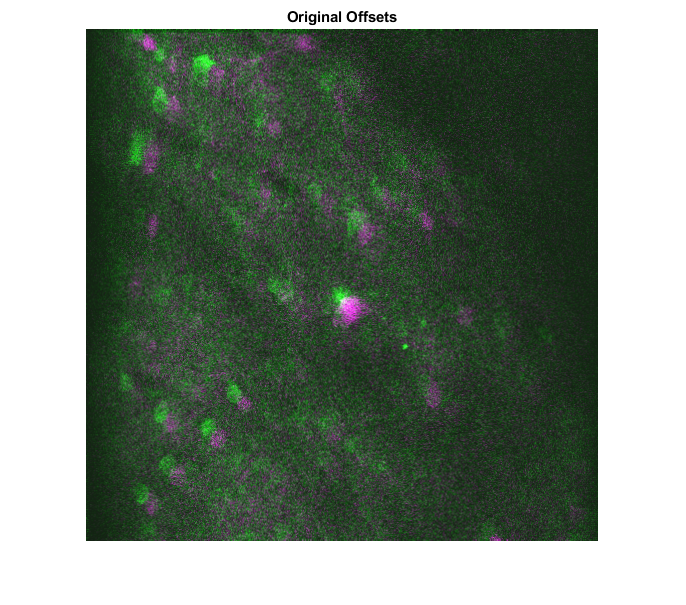


% registered_imageInfo_prev.currRegisteredImage = imds.registered_prev.readimage(registered_imageInfo_prev.imgStackSize.numberOfFrames); % Get the last from the first prev stack
% registered_imageInfo_next.currRegisteredImage = imds.registered_next.readimage(1); % Get first frame from the next stack

% Original Offset:
figure
imshowpair(registered_imageInfo_prev.currRegisteredImage, registered_imageInfo_next.currRegisteredImage)
title('Original Offsets')

## Normalized Cross Correlation Method

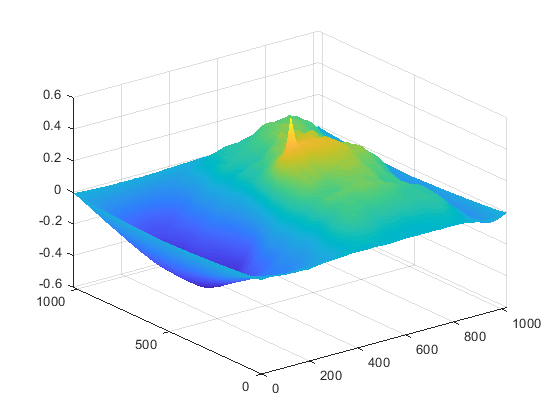

c = normxcorr2(registered_imageInfo_prev.currRegisteredImage, registered_imageInfo_next.currRegisteredImage);
figure;
surf(c)
shading flat


[ypeak,xpeak] = find(c==max(c(:)));
yoffSet = ypeak-size(registered_imageInfo_prev.currRegisteredImage, 1);
xoffSet = xpeak-size(registered_imageInfo_prev.currRegisteredImage, 2);
% Build translation-only affine2d transform:
T = [1 0 0; 0 1 0; -xoffSet -yoffSet 1];
tform = affine2d(T);

% fixedPoints = [0, 0];
% movingPoints = fixedPoints + [xoffSet, yoffSet];
% 
% % tform = fitgeotrans(movingPoints,fixedPoints,'NonreflectiveSimilarity')
% tform = fitgeotrans(movingPoints,fixedPoints,'NonreflectiveSimilarity')


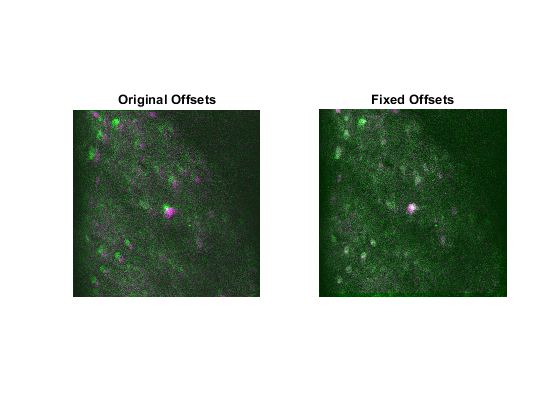


% Shows simple offset:
figure
Rfixed = imref2d(size(registered_imageInfo_next.currRegisteredImage));
registered = imwarp(registered_imageInfo_next.currRegisteredImage, tform, 'OutputView', Rfixed);
% imshowpair(registered_imageInfo_next.currRegisteredImage, registered) % Shows change from original next image
% imshow([imagedata1, imagedata2])
subplot(1,2,1)
imshowpair(registered_imageInfo_prev.currRegisteredImage, registered_imageInfo_next.currRegisteredImage)
title('Original Offsets')
subplot(1,2,2)
imshowpair(registered_imageInfo_prev.currRegisteredImage, registered)
title('Fixed Offsets')

## Interactive Point-based Alignment

[mp,fp] = cpselect(registered_imageInfo_next.currRegisteredImage, registered_imageInfo_prev.currRegisteredImage, 'Wait', true);
% save('outPho.mat','mp','fp','-mat')

% t = fitgeotrans(mp, fp, 'projective'); % Returns projective2d object
tform = fitgeotrans(mp, fp, 'NonreflectiveSimilarity'); % returns affine2d object

u = [0 1]; 
v = [0 0]; 
[x, y] = transformPointsForward(tform, u, v); 
dx = x(2) - x(1); 
dy = y(2) - y(1); 
angle = (180/pi) * atan2(dy, dx) 

angle = -0.4540

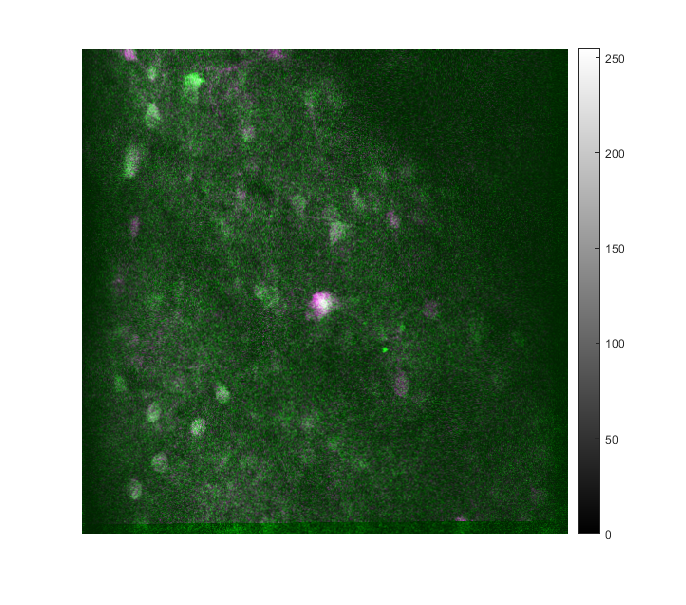



Rfixed = imref2d(size(registered_imageInfo_prev.currRegisteredImage));
registered = imwarp(registered_imageInfo_next.currRegisteredImage, tform, 'OutputView', Rfixed);
imshowpair(registered_imageInfo_prev.currRegisteredImage, registered)

title('Fixed offsets')

[offset_first_to_second, debugStructures] = fnPhoComputeRegistrationOffset(registered_imageInfo_prev.currRegisteredImage, registered_imageInfo_next.currRegisteredImage)

offset_first_to_second =    -11   -10


debugStructures = struct with fields:
    crossCorrelation: [1023×1023 double]
               tform: [1×1 affine2d]


[convolvedProduct.indexI, convolvedProduct.indexJ] = ind2sub(size(registered_imageInfo_prev.currRegisteredImage), offset_first_to_second) % Convert linear index to offset

convolvedProduct = struct with fields:
    indexI: 259
    indexJ: 140


convolvedProduct = struct with fields:
    indexI: 259
    indexJ: 140



% rawSubpath = 'E:\PhoHaleScratchFolder\20200120_PassiveStim\FoV1Lateral';
% rawTifFolder = rawSubpath; % tifs are just directly in this folder. There is also a .h5 file
% 
% % rawH5FileName = '20200120_PassiveStimIC_FoV1Lateral_0001-0520.h5';
% 
% registeredSubpath = 'E:\PhoHaleScratchFolder\20200120_PassiveStim_Registered\FoV1Lateral\suite2p\plane0';
% registeredTifFolder = fullfile(registeredSubpath, 'reg_tif');

% imds.raw.ReadFcn = @fnCustomTifStackReader;
% imds.registered.ReadFcn = @fnCustomTifStackReader;
% 
% imds.raw = imageDatastore(rawTifFolder,'IncludeSubfolders',false,'FileExtensions','.tif','LabelSource','foldernames');
% imds.registered = imageDatastore(registeredTifFolder,'IncludeSubfolders',false,'FileExtensions','.tif','LabelSource','foldernames');


% Load the current data:
% fileName = imds.registered.Files{1}

fileName = 'E:\PhoHaleScratchFolder\20200120_PassiveStim_Registered\FoV1Lateral\suite2p\plane0\reg_tif\file000_chan0.tif'

% currLoadedData = bfOpen3DVolume(fileName);

Reading series #1
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ......................................................

% currLoadedImgStack = currLoadedData{1,1}{1,1}; % Produces the desired 512x512x2000 (2000 frames per .tif) output
% imgStackSize.numberOfFrames = size(currLoadedImgStack,3);


% figure; montage(imgStack,[])

%     close(t);

## Done loading

% % imshow(preview(imds.raw))
% i = 1; % curr index
% currRawImage = imds.raw.readimage(i);
% currRegisteredImage = imds.registered.readimage(i);
% % info = imfinfo('ngc6543a.jpg');

